clc, clear, close all
syms z n Y X
X1 = z^(-1)*X;
X2 = z^(-2)*X;
Y1 = z^(-1)*Y;
Y2 = z^(-2)*Y;
G = -Y + 1.5*Y1 - 0.9*Y2 + X + 0.7*X1 + 0.6*X2;
SOL = solve(G,Y)

$$SOL = \frac{10\,X\,z^{2}+7\,X\,z+6\,X}{10\,z^{2}-15\,z+9}$$

H = simplify((SOL)/(X))

$$H = \frac{10\,z^{2}+7\,z+6}{10\,z^{2}-15\,z+9}$$

imp = zeros(1,100);
imp(1) = imp(1)+1;
y = filter([10 7 6],[10 -15 9],imp)

y =     1.0000    2.2000    3.0000    2.5200    1.0800   -0.6480   -1.9440   -2.3328   -1.7496   -0.5249    0.7873    1.6534    1.7715    1.1692    0.1594   -0.8131   -1.3631   -1.3129   -0.7426    0.0678    0.7700    1.0940    0.9480    0.4374   -0.1971   -0.6893   -0.8566   -0.6645   -0.2258    0.2593    0.5922    0.6549    0.4494    0.0847   -0.2775   -0.4924   -0.4889   -0.2901    0.0048    0.2683    0.3981    0.3557    0.1753   -0.0572   -0.2436   -0.3139   -0.2516   -0.0949    0.0841    0.2115


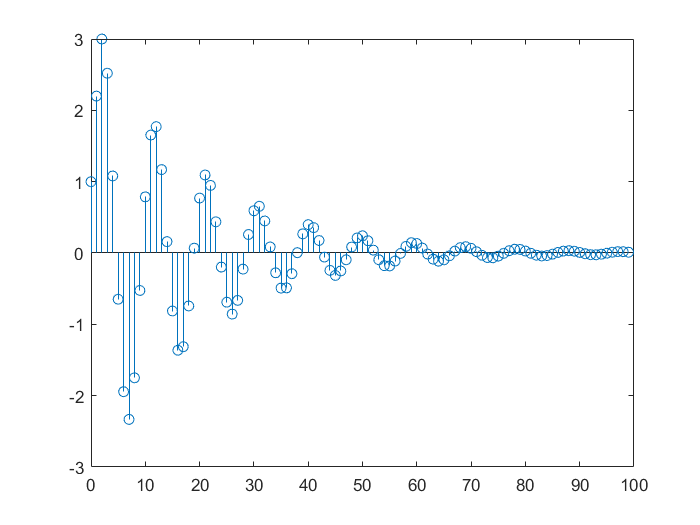

stem(0:99,y)

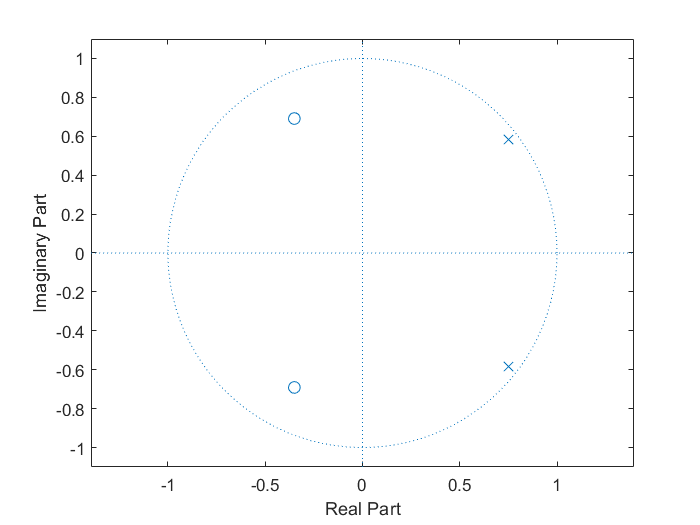

figure
zplane([10 7 6],[10 -15 9])

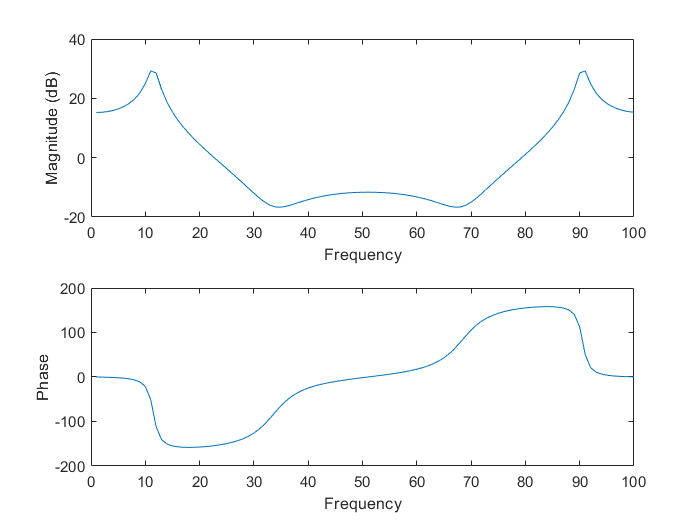


IMP = fft(y,100);
figure
subplot(2,1,1)
plot(20*log10(abs(IMP)))
xlabel('Frequency')
ylabel('Magnitude (dB)')

subplot(2,1,2)
plot(angle(IMP)*180/pi)
xlabel('Frequency')
ylabel('Phase')